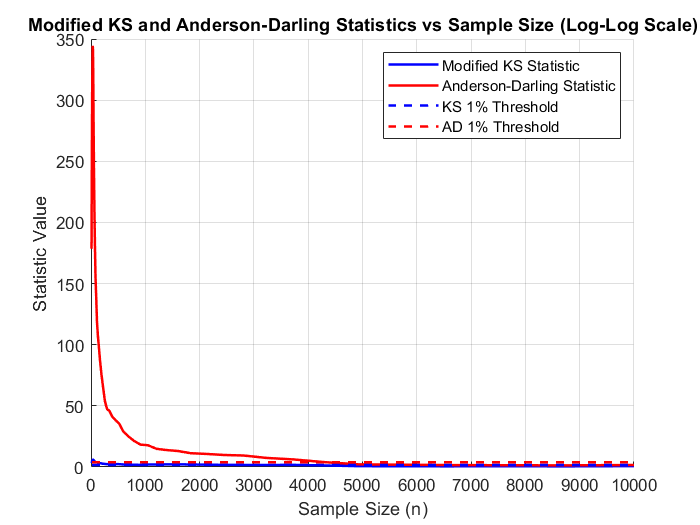

% Define parameters
n_values = round(logspace(1, 4, 50)); % Log-spaced sample sizes from 10 to 10,000
ks_threshold = 1.628; % 1% significance level for KS statistic
ad_threshold = 3.857; % 1% significance level for Anderson-Darling statistic

% Initialize result storage
modified_ks_values = zeros(size(n_values));
anderson_darling_values = zeros(size(n_values));

% Define Uniform CDF Function
F_uniform = @(x) x;

% Loop over different sample sizes
for i = 1:length(n_values)
    n = n_values(i);
    
    % Generate Fibonacci RNG sequence
    fibonacci_rng = myfibonacci(n, 1, 1, 2^31);
    
    % Compute KS Statistic
    ks_fib = KS_statistic(fibonacci_rng, F_uniform);
    
    % Compute Modified KS Statistic
    modified_ks_values(i) = modifiedKS(ks_fib, n);
    
    % Compute Anderson-Darling Statistic
    anderson_darling_values(i) = anderson_darling(fibonacci_rng, F_uniform);
end

% Plot results using log-log scale
figure; hold on;
loglog(n_values, modified_ks_values, 'b', 'LineWidth', 1.5); % Modified KS (blue)
loglog(n_values, anderson_darling_values, 'r', 'LineWidth', 1.5); % Anderson-Darling (red)

% Add 1% significance level lines in log scale
loglog([min(n_values), max(n_values)], [ks_threshold, ks_threshold], 'b--', 'LineWidth', 1.5, 'DisplayName', 'KS 1% Threshold');
loglog([min(n_values), max(n_values)], [ad_threshold, ad_threshold], 'r--', 'LineWidth', 1.5, 'DisplayName', 'AD 1% Threshold');

% Formatting
xlabel('Sample Size (n)');
ylabel('Statistic Value');
title('Modified KS and Anderson-Darling Statistics vs Sample Size (Log-Log Scale)');
legend('Modified KS Statistic', 'Anderson-Darling Statistic', 'KS 1% Threshold', 'AD 1% Threshold');
grid on; hold off;


clear;

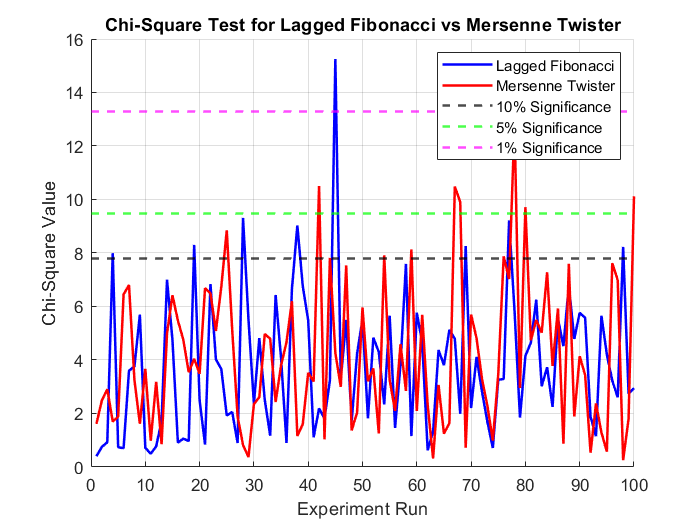

% Experiment Parameters
num_experiments = 100; % Number of runs
n2 = 2000; % Sample size
k1 = 10;
k2 = 1;

% Gap Test Parameters
a = 0;
b = 3/4;
t = 4; % Degrees of freedom for chi-squared

% Initialize storage for Chi-Square values
chi2_lagfib_values = zeros(1, num_experiments);
chi2_mt_values = zeros(1, num_experiments);

% Run multiple experiments
for exp = 1:num_experiments
    % Generate a new random seed for Lagged Fibonacci in each iteration
    seed = randi([1, 2^31], 1, k1); % Generate k1 random integers as seed

    % Generate sequences
    lag_fibonacci = lagged_fibonacci(n2, seed, k1, k2, 2^35);
    mersenne = rand(1, n2);

    % Perform gap test
    [gap_fib, Pvals_fib] = gaps(lag_fibonacci, a, b, t);
    [gap_mt, Pvals_mt] = gaps(mersenne, a, b, t);

    % Compute total events
    total_events_fib = sum(gap_fib);
    total_events_mt = sum(gap_mt);

    % Compute Chi-Square values
    chi2_lagfib_values(exp) = chi_squared(gap_fib, Pvals_fib, total_events_fib);
    chi2_mt_values(exp) = chi_squared(gap_mt, Pvals_mt, total_events_mt);
end

% Compute Chi-Square significance thresholds
chi2_threshold_10 = chi2inv(0.90, t); % 10% significance level
chi2_threshold_5 = chi2inv(0.95, t);  % 5% significance level
chi2_threshold_1 = chi2inv(0.99, t);  % 1% significance level

% Plot results
figure; hold on;

% Plot Chi-Square values
plot(1:num_experiments, chi2_lagfib_values, 'b', 'LineWidth', 1.5, 'DisplayName', 'Lagged Fibonacci');
plot(1:num_experiments, chi2_mt_values, 'r', 'LineWidth', 1.5, 'DisplayName', 'Mersenne Twister');

% Add significance threshold lines
yline(chi2_threshold_10, 'k--', 'LineWidth', 1.5, 'DisplayName', '10% Significance');
yline(chi2_threshold_5, 'g--', 'LineWidth', 1.5, 'DisplayName', '5% Significance');
yline(chi2_threshold_1, 'm--', 'LineWidth', 1.5, 'DisplayName', '1% Significance');

% Formatting
xlabel('Experiment Run');
ylabel('Chi-Square Value');
title('Chi-Square Test for Lagged Fibonacci vs Mersenne Twister');
legend();
grid on;
hold off;


clear;

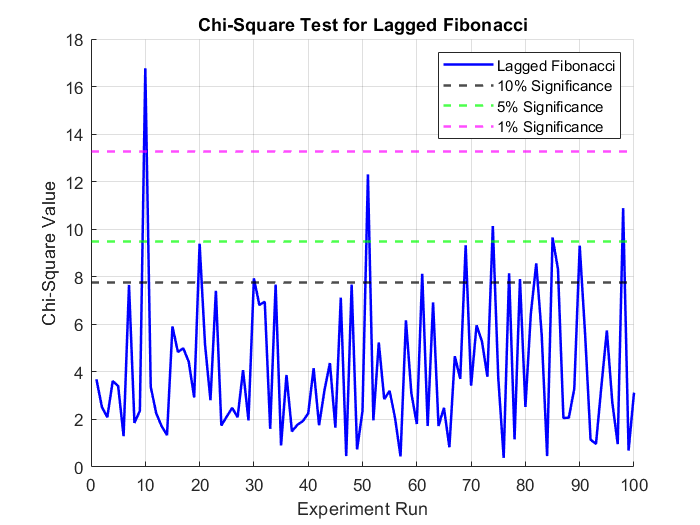

% Experiment Parameters
num_experiments = 100; % Number of runs
n2 = 2000; % Sample size
k1 = 16;
k2 = 1;

% Gap Test Parameters
a = 0;
b = 3/4;
t = 4; % Degrees of freedom for chi-squared

% Initialize storage for Chi-Square values
chi2_lagfib_values = zeros(1, num_experiments);

% Run multiple experiments
for exp = 1:num_experiments
    % Generate a new random seed for Lagged Fibonacci in each iteration
    seed = randi([1, 2^31], 1, k1); % Generate k1 random integers as seed

    % Generate Lagged Fibonacci sequence
    lag_fibonacci = lagged_fibonacci(n2, seed, k1, k2, 2^35);

    % Perform gap test
    [gap_fib, Pvals_fib] = gaps(lag_fibonacci, a, b, t);

    % Compute total events
    total_events_fib = sum(gap_fib);

    % Compute Chi-Square values
    chi2_lagfib_values(exp) = chi_squared(gap_fib, Pvals_fib, total_events_fib);
end

% Compute Chi-Square significance thresholds
chi2_threshold_10 = chi2inv(0.90, t); % 10% significance level
chi2_threshold_5 = chi2inv(0.95, t);  % 5% significance level
chi2_threshold_1 = chi2inv(0.99, t);  % 1% significance level

% Plot results
figure; hold on;

% Plot Chi-Square values for Lagged Fibonacci
plot(1:num_experiments, chi2_lagfib_values, 'b', 'LineWidth', 1.5, 'DisplayName', 'Lagged Fibonacci');

% Add significance threshold lines
yline(chi2_threshold_10, 'k--', 'LineWidth', 1.5, 'DisplayName', '10% Significance');
yline(chi2_threshold_5, 'g--', 'LineWidth', 1.5, 'DisplayName', '5% Significance');
yline(chi2_threshold_1, 'm--', 'LineWidth', 1.5, 'DisplayName', '1% Significance');

% Formatting
xlabel('Experiment Run');
ylabel('Chi-Square Value');
title('Chi-Square Test for Lagged Fibonacci');
legend();
grid on;
hold off;


clear;


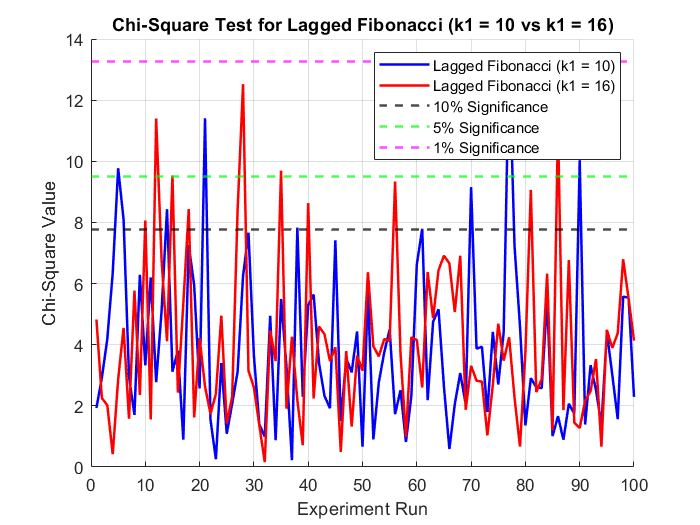

% Experiment Parameters
num_experiments = 100; % Number of runs
n2 = 2000; % Sample size
k1_1 = 10; % First lag parameter
k1_2 = 16; % Second lag parameter
k2 = 1;

% Gap Test Parameters
a = 0;
b = 3/4;
t = 4; % Degrees of freedom for chi-squared

% Initialize storage for Chi-Square values
chi2_lagfib_10 = zeros(1, num_experiments);
chi2_lagfib_16 = zeros(1, num_experiments);

% Run multiple experiments
for exp = 1:num_experiments
    % Generate new random seeds for each generator in every iteration
    seed_10 = randi([1, 2^31], 1, k1_1);
    seed_16 = randi([1, 2^31], 1, k1_2);

    % Generate Lagged Fibonacci sequences
    lag_fibonacci_10 = lagged_fibonacci(n2, seed_10, k1_1, k2, 2^35);
    lag_fibonacci_16 = lagged_fibonacci(n2, seed_16, k1_2, k2, 2^35);

    % Perform gap test
    [gap_fib_10, Pvals_fib_10] = gaps(lag_fibonacci_10, a, b, t);
    [gap_fib_16, Pvals_fib_16] = gaps(lag_fibonacci_16, a, b, t);

    % Compute total events
    total_events_10 = sum(gap_fib_10);
    total_events_16 = sum(gap_fib_16);

    % Compute Chi-Square values
    chi2_lagfib_10(exp) = chi_squared(gap_fib_10, Pvals_fib_10, total_events_10);
    chi2_lagfib_16(exp) = chi_squared(gap_fib_16, Pvals_fib_16, total_events_16);
end

% Compute Chi-Square significance thresholds
chi2_threshold_10 = chi2inv(0.90, t); % 10% significance level
chi2_threshold_5 = chi2inv(0.95, t);  % 5% significance level
chi2_threshold_1 = chi2inv(0.99, t);  % 1% significance level

% Plot results
figure; hold on;

% Plot Chi-Square values for both generators
plot(1:num_experiments, chi2_lagfib_10, 'b', 'LineWidth', 1.5, 'DisplayName', 'Lagged Fibonacci (k1 = 10)');
plot(1:num_experiments, chi2_lagfib_16, 'r', 'LineWidth', 1.5, 'DisplayName', 'Lagged Fibonacci (k1 = 16)');

% Add significance threshold lines
yline(chi2_threshold_10, 'k--', 'LineWidth', 1.5, 'DisplayName', '10% Significance');
yline(chi2_threshold_5, 'g--', 'LineWidth', 1.5, 'DisplayName', '5% Significance');
yline(chi2_threshold_1, 'm--', 'LineWidth', 1.5, 'DisplayName', '1% Significance');

% Formatting
xlabel('Experiment Run');
ylabel('Chi-Square Value');
title('Chi-Square Test for Lagged Fibonacci (k1 = 10 vs k1 = 16)');
legend();
grid on;
hold off;


clear;


